# Probando diferentes métodos de derivación numérica

Comparación entre los diferentes métodos de derivación numérica para la primera derivada, y exploración de un método para la segunda derivada, estos métodos son

aproximación hacia delante,


$$f'(x) \approx \frac{f(x+h) - f(x)}{h}$$


aproximación hacia atrás,


$$f'(x) \approx \frac{f(x) - f(x-h)}{h}$$


aproximación centrada abreviada,


$$f'(x) \approx \frac{f(x+h) - f(x-h)}{2h}$$


y, aproximación centrada


$$f'(x) \approx \frac{-f(x+2h) + 8f(x+h) - 8f(x-h) + f(x-2h)}{12h}$$


para la primera derivada. Para la segunda derivada tenemos la aproximación centrada abreviada


$$f''(x) \approx \frac{f(x+h) - 2f(x) + f(x-h)}{h^2}$$


## Primera derivada

Los parámetros y vectores de prueba que serán utilizados están declarados e instanciados aquí

syms x
f1 = -0.1*x^4 - 0.15*x^3 - 0.5*x^2 - 0.25*x + 1.2; % funcion de prueba
f2 = x^6 - 1; % funcion de prueba

p = 0.5; % punto alrededor del que se calcula la derivada
z = 0:32; % vector de las iteraciones de h
n = length(z); % tamaño del vector anterior
u = zeros(1, n); % vector para guardar los valores de la primera derivada de f1
y = zeros(1, n); % vector para guardar los valores de la primera derivada de f1

hF1 = zeros(1, n); % vector para guardar el tamaño de h de cada iteracion de la derivada de f1
errorsF1 = zeros(1, n); % vector para guardar el error absoluto de la derivada de f1
hF2 = zeros(1, n); % vector para guardar el tamaño de h de cada iteracion de la derivada de f2
errorsF2 = zeros(1, n); % vector para guardar el error absoluto de la derivada de f2
f1P = subs(diff(f1), x, p); % derivada de f1 simbolica evaluada en el punto a analizar
f2P = subs(diff(f2), x, p); % derivada de f1 simbolica evaluada en el punto a analizar

### Aproximación hacia adelante

Usando, aproximaremos la derivada, esto utilizando diferentes parámetros de $h$, empezando desde 1, para probar si disminuir $h$ hace una diferencia en el error absoluto o no.

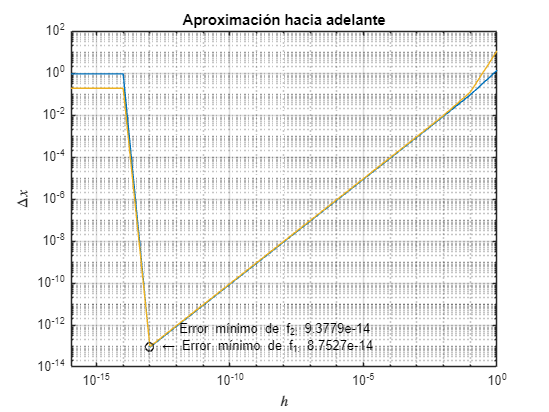

% calcular los valores
parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        primeraDerivadaAdelante(f1, x, [p p+step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        primeraDerivadaAdelante(f2, x, [p p+step], f2P);
end

[ymin, idx] = min(errorsF1); % obtener el error minimo calculado en f1 y su iteracion

loglog(hF1, errorsF1) % graficar los errores de f1 en escala logaritmica

grid on
hold on

loglog(hF1(idx), ymin, 'ko') % graficar el valor minimo encontrado para f1
text(hF1(idx), ymin, [' \leftarrow Error mínimo de f_1: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2); % obtener el error minimo calculado en f1 y su iteracion
loglog(hF2(idx), ymin, 'ko') % graficar dicho valor
text(hF2(idx), ymin+5*ymin, ['    Error mínimo de f_2: ',num2str(ymin)]);

hold off

title('Aproximación hacia adelante')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

### Aproximación hacia atrás

Repitiendo el experimento anterior, pero ahora utilizando el método de diferenciación hacia atrás $f'(x) \approx \frac{f(x) - f(x-h)}{h}$.

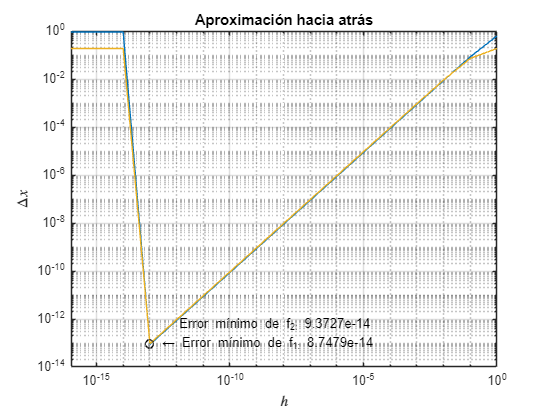

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        primeraDerivadaAtras(f1, x, [p p-step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        primeraDerivadaAtras(f2, x, [p p-step], f2P);
end

[ymin, idx] = min(errorsF1);

loglog(hF1, errorsF1)

grid on
hold on

loglog(hF1(idx), ymin, 'ko')
text(hF1(idx), ymin, [' \leftarrow Error mínimo de f_1: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+5*ymin, ['    Error mínimo de f_2: ',num2str(ymin)]);

hold off

title('Aproximación hacia atrás')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

### Aproximación centrada abreviada

Lo mismo que los dos experimentos pasados, pero ahora utilizando el método de aproximación centrada abreviada, definido como

$f'(x) \approx \frac{f(x+h) - f(x-h)}{2h}$.

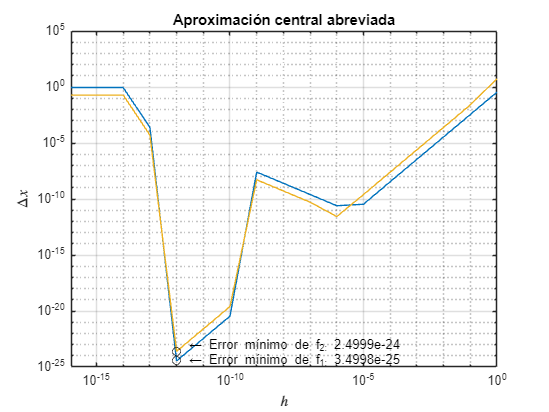

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        primeraDerivadaCentradaAbreviada(f1, x, [p+step p p-step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        primeraDerivadaCentradaAbreviada(f2, x, [p+step p p-step], f2P);
end

[ymin, idx] = min(errorsF1);

loglog(hF1, errorsF1)

grid on
hold on

loglog(hF1(idx), ymin, 'ko')
text(hF1(idx), ymin, [' \leftarrow Error mínimo de f_1: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+2*ymin, [' \leftarrow Error mínimo de f_2: ',num2str(ymin)]);

hold off

title('Aproximación central abreviada')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

### Aproximación centrada

Lo mismo que los anteriores tres experimentos, pero ahora utilizando el método de aproximación centrada, definido como $f'(x) \approx \frac{-f(x+2h) + 8f(x+h) - 8f(x-h) + f(x-2h)}{12h}$.

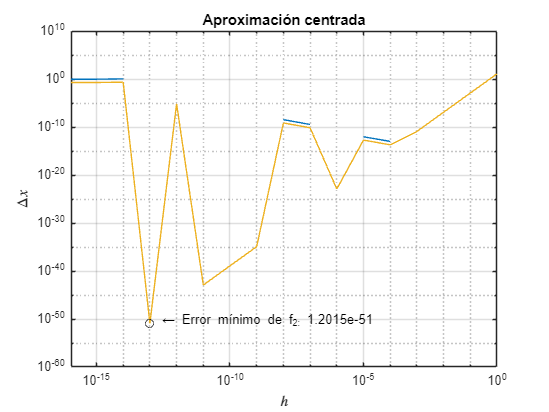

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        primeraDerivadaCentrada(f1, x, [p+2*step p+step p p-step p-2*step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        primeraDerivadaCentrada(f2, x, [p+2*step p+step p p-step p-2*step], f2P);
end

loglog(hF1, errorsF1, 'Color','#0072BD')

% sorprendentemente para f1 tenemos valores con error 0, esto significa dos
% cosas, error de truncación o de redondeo, para averiguar esto, tendremos
% que utilizar valores con mayor número de bits para los números decimales

grid on
hold on

loglog(hF2, errorsF2, 'color','#EDB120')
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+2*ymin, [' \leftarrow Error mínimo de f_2: ',num2str(ymin)]);

hold off

title('Aproximación centrada')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

## Segunda derivada

Aquí definimos los parámetros a utilizarse en el experimento de la aproximación a la segunda derivada.

f1PP = subs(diff(diff(f1)), x, p);
f2PP = subs(diff(diff(f2)), x, p);

### Aproximación centrada abreviada

Repitiendo el mismo experimento que antes, pero ahora calculando la segunda derivada, esto utilizando el método de la aproximación centrada abreviada, definido como $f''(x) \approx \frac{f(x+h) - 2f(x) + f(x-h)}{h^2}$.

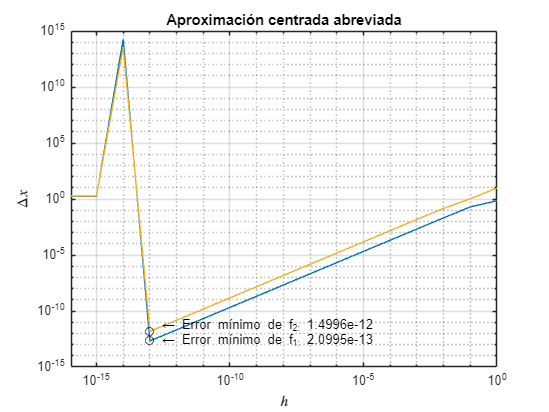

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        segundaDerivadaCentradaAbreviada(f1, x, [p+step p p-step], f1PP);

    [y(i), hF2(i), errorsF2(i)] = ...
        segundaDerivadaCentradaAbreviada(f2, x, [p+step p p-step], f2PP);
end

[ymin, idx] = min(errorsF1);

loglog(hF1, errorsF1)

grid on
hold on

loglog(hF1(idx), ymin, 'ko')
text(hF1(idx), ymin, [' \leftarrow Error mínimo de f_1: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+2*ymin, [' \leftarrow Error mínimo de f_2: ',num2str(ymin)]);

hold off

title('Aproximación centrada abreviada')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

## Conclusión

Después de estudiar diferentes métodos de derivación numérica (aproximación hacia adelante, hacia atras, centrada abreviada y centrada), podemos ver que disminuyendo $h$ si hay una diferencia en los diferentes errores.

Cada que disminuimos $h$, observamos una aproximación mucho mayor a la derivada simbólica. Pero al mismo tiempo, esta disminución puede generar errores de truncación o de redondeo de la aproximación, lo que nos arroja un error nulo. La elección de que método utilizar depende en la precisión que requiramos para nuestras necesidades. Este experimento muestra gráficamente el comportamiento del error. Por cada serie de pruebas, el punto crítico que representa un mínimo local obtenido (el punto ideal de $h$ que nos da el error mínimo) es mostrado, después de esto, empiezan errorres de redondeo y truncación que nos previene de seleccionar una $h$ demasiado pequeña.

Para concluir, el código provee un buen analisis del rendimiento de diferentes métodos de derivación numérica, mostrando la precisión de acuerdo a las variaciones de los escalones. La visualización de los errores y la señalización del error mínimo sirven para entender el comportamiento de los diferentes métodos, así como las características específicas de las funciones y su precisión deseada.

## References

- Steven Chapra & Raymond Canale, (2015). Cap.21, *Métodos Numéricos para Ingenieros (pp.548-560)*, McGraw- Hill, Séptima edición, 2015. 

- Matlab (2024). *Matlab*. Recuperado el 28 de enero de 2024 de: [MATLAB Documentation - MathWorks América Latina](https://la.mathworks.com/help/matlab/)